Caso x=1.5m y=0.5m

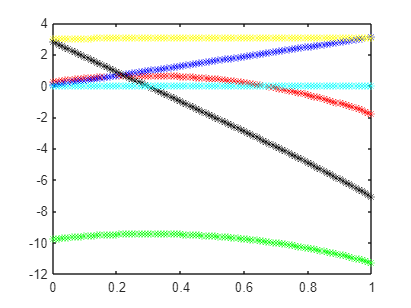

v0=4.3;
angulo=45;
vx0=4.3.*cos(deg2rad(45));
vy0=4.3*sin(deg2rad(45));
x0=0;
y0=0.2051;
dt=0.01;
ax0=0;
ay0=-9.8;
A=0.00098;
Roaire=1.01;
Cd=0.47;
b=0.000232603;
m=0.03;

x=x0+vx0.*dt;
vx=vx0+ax0.*dt;

y=y0+vy0.*dt;
vy=vy0+ay0.*dt;

ay=ay0+(b.*vy0)/m;
ax=(b.*vx0/m);

for t=0:0.01:1
    ax=(b.*vx)/m;
    vx=vx+ax.*dt;
    x=x+vx.*dt;

    ay=ay+(b.*vy)/m;
    vy=vy+ay.*dt;
    y=y+vy.*dt;

    plot(t,y,"*red")
    hold on 

    plot(t,x,"*blue")
    hold on
   
    plot(t,vx,"*yellow")
    hold on 

    plot(t,vy,"*black")
    hold on
   
    plot(t,ax, "*cyan")
    hold on 

    plot(t,ay,"*green")
    hold on
   
end